clf; clear;
img = imread("../images/fingerprint.tif");
[P, Q] = size(img);
img = double(img) / 255;

filter = fspecial("gaussian", 30, 5);
blur_img = imfilter(img, filter);

g_x = imfilter(blur_img, [-1, 1]');
g_y = imfilter(blur_img, [-1, 1]);
M = sqrt(g_x .^ 2 + g_y .^ 2);
A = atand(g_y ./ (g_x + 1e-9));

pad_M = padarray(M, [1, 1], "symmetric", "both");
NMS_M = zeros([P, Q]);
for x=1:P
    for y=1:Q
        angle = mod(A(x, y) + 202.5, 180);
        if angle >= 0 && angle < 45
            n_1 = pad_M(x, y+1);
            n_2 = pad_M(x+2, y+1);
        elseif angle >= 45 && angle < 90
            n_1 = pad_M(x, y);
            n_2 = pad_M(x+2, y+2);
        elseif angle >= 90 && angle < 135
            n_1 = pad_M(x+1, y);
            n_2 = pad_M(x+1, y+2);
        elseif angle >= 135 && angle < 180
            n_1 = pad_M(x, y+2);
            n_2 = pad_M(x+2, y);
        end

        if pad_M(x+1, y+1) > n_1 && pad_M(x+1, y+1) > n_2
            NMS_M(x, y) = pad_M(x+1, y+1);
        end
    end
end

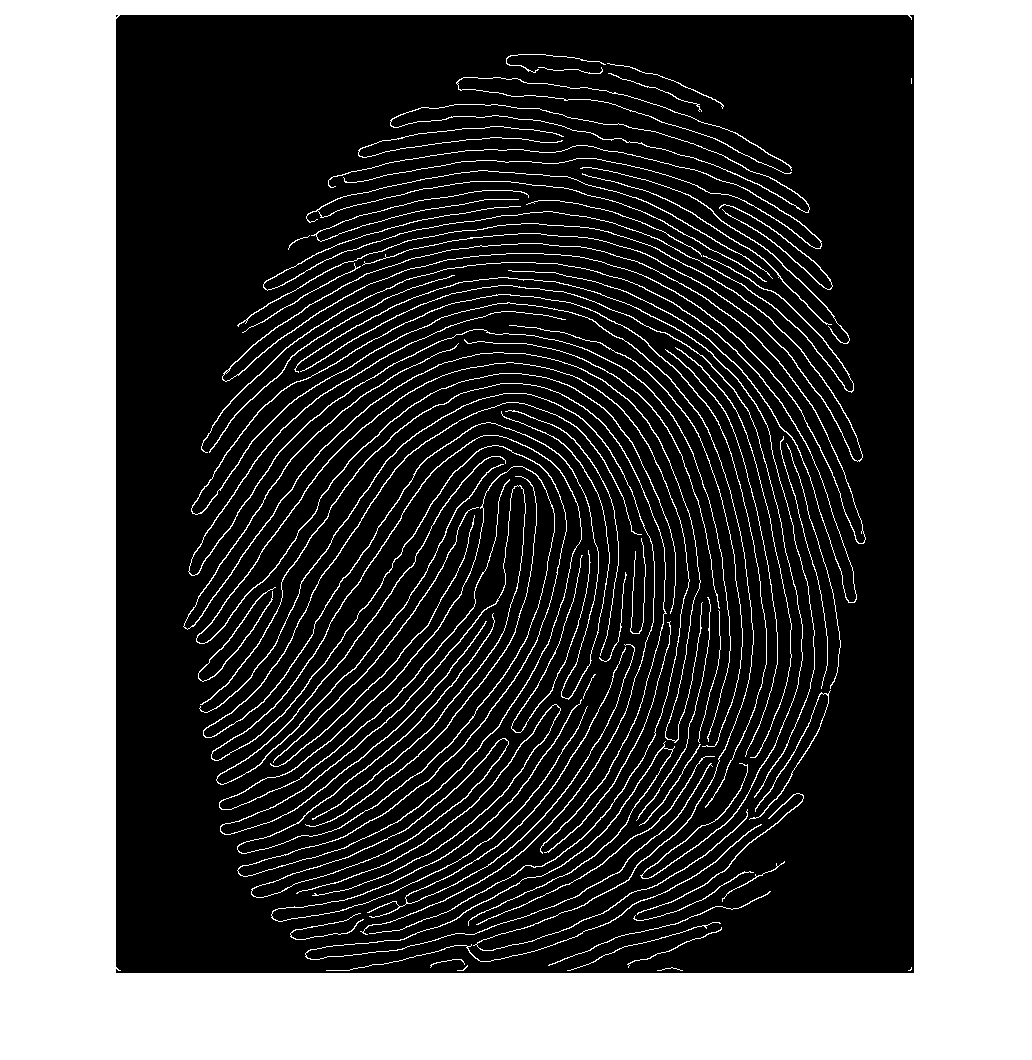

T_L = 0.2;
T_H = 0.48;
G_L = imbinarize(NMS_M / max(max(NMS_M)), T_L);
G_H = imbinarize(NMS_M / max(max(NMS_M)), T_H);
[r, c] = find(G_H);
res = bwselect(G_L, c, r, 8);

imshow(res, [])